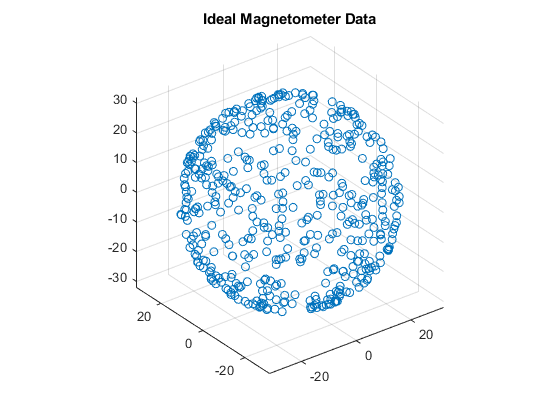

N = 500;
rng(1);
acc = zeros(N,3);
av = zeros(N,3);
q = randrot(N,1); % uniformly distributed random rotations
imu = imuSensor('accel-mag');
[~,x] = imu(acc,av,q);
scatter3(x(:,1),x(:,2),x(:,3));
axis equal
title('Ideal Magnetometer Data');

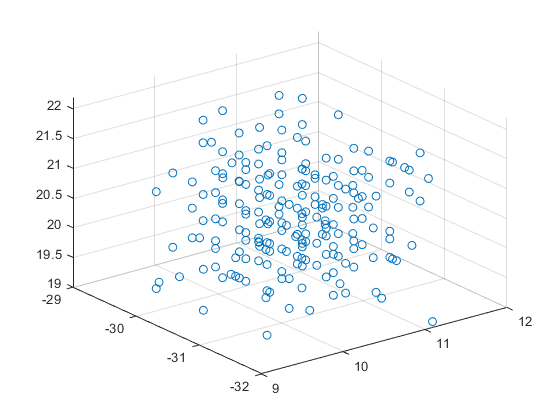

scatter3(Magnetometer(:,1),Magnetometer(:,2),Magnetometer(:,3))

[A,b,expMFS]  = magcal(Magnetometer);
xCorrected = (Magnetometer-b)*A;
de = HelperDrawEllipsoid;
de.plotCalibrated(A,b,expMFS,Magnetometer,xCorrected,'Auto');
clear("de")

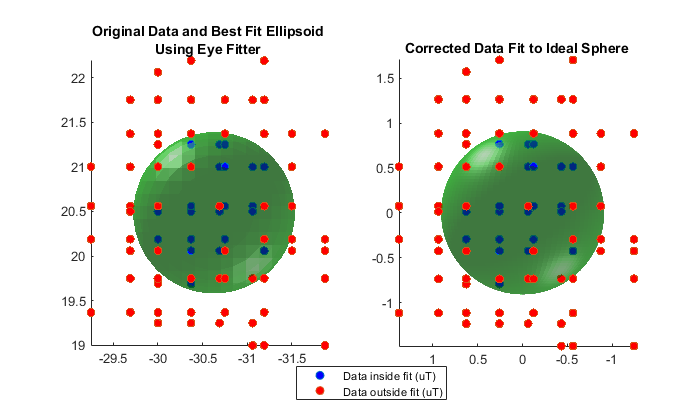

[Aeye,beye,expMFSeye] = magcal(Magnetometer,'eye');
xEyeCorrected = (Magnetometer-beye)*Aeye;
de = HelperDrawEllipsoid;
[ax1,ax2] = de.plotCalibrated(Aeye,beye,expMFSeye,Magnetometer,xEyeCorrected,'Eye');
view(ax1,[-1 0 0]);
view(ax2,[-1 0 0]);

nedmf = imu.MagneticField;
Rsoft = [2.5 0.3 0.5; 0.3 2 .2; 0.5 0.2 3];
soft = rotateframe(conj(q),rotateframe(q,nedmf)*Rsoft);

mu.Magnetometer.NoiseDensity = 0.08;
for ii=1:numel(q)
    imu.MagneticField = soft(ii,:);
    [~,x(ii,:)] = imu(acc(ii,:),av(ii,:),q(ii));
end

scatter3(x(:,1),x(:,2),x(:,3));
axis equal
title('Magnetometer Data With Hard and Soft Iron Effects');

[A,b,expMFS]  = magcal(x);
xCorrected = (x-b)*A;
de = HelperDrawEllipsoid;
de.plotCalibrated(A,b,expMFS,x,xCorrected,'Auto');